clear;

data_dir = '.\data\';
[features,labels,filename] = txt2data(data_dir);
len = length(labels)

len = 385

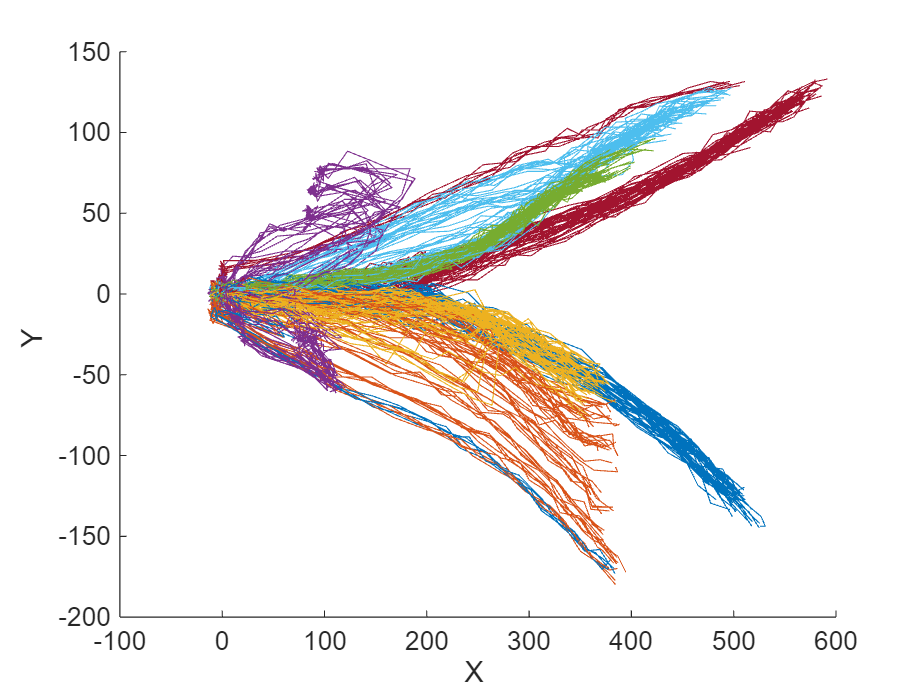

figure; 
hold on; 
color = {[0 0.4470 0.7410], [0.8500 0.3250 0.0980], [0.9290 0.6940 0.1250], [0.4940 0.1840 0.5560], [0.4660 0.6740 0.1880],[0.3010 0.7450 0.9330],[0.6350 0.0780 0.1840]};
for i = 1:len
    data = features{i}; 
    label = labels(i)+4;
    file = filename{i};
    plot3(data(1,:), data(2,:), data(3,:),'Color',color{label}); 
end
hold off; 
xlabel('X ', 'FontSize', 14); 
ylabel('Y ', 'FontSize', 14); 
zlabel('Z ', 'FontSize', 14);
set(gca, 'FontSize', 12); 

% grid on


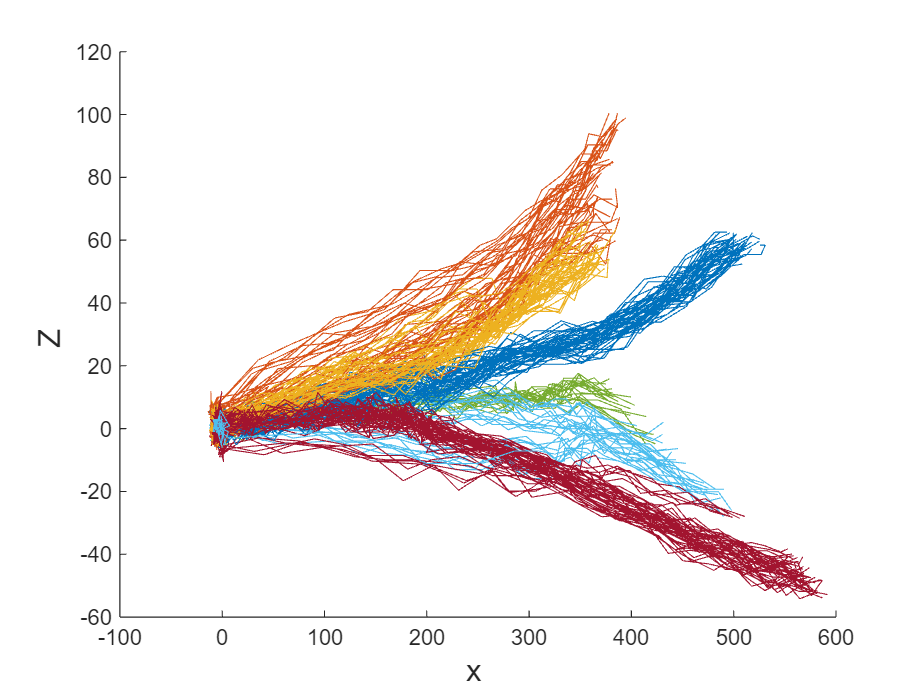

figure; 
hold on; 
color = {[0 0.4470 0.7410], [0.8500 0.3250 0.0980], [0.9290 0.6940 0.1250], [0.4940 0.1840 0.5560], [0.4660 0.6740 0.1880],[0.3010 0.7450 0.9330],[0.6350 0.0780 0.1840]};
for i = 1:248
    data = features{i}; 
    label = labels(i)+4;
    plot(data(1,:), data(3,:),'Color',color{label}); 
end
hold off; 
xlabel('x ', 'FontSize', 14); 
ylabel('Z ', 'FontSize', 14); 

% grid on;